# comparing the CJF visual classification to pilot

We compare the zooniverse classification to the expert classification in the 2 pilot projects (TNG100  - Yun 2019 & TNG50) on the object matched subsample. 

## perliminaries

global illUnits
global DEFAULT_MATFILE_DIR

## load CJF sample

load([DEFAULT_MATFILE_DIR '/cosmic_jellyfish_objectTable.mat'])
objectCJF=objectTable;

## Load Yun2019 sample


load([DEFAULT_MATFILE_DIR '/yun19_jellyfish_objectTable.mat'])


## load TNG50 pilot sample

load([DEFAULT_MATFILE_DIR '/jf_objectTable_TNG50.mat'])
load([DEFAULT_MATFILE_DIR '/jellyfishScores_TNG50.mat'])
objectTNG50=objectTable;



## compare TNG50 to CJF

% find subsample 

mask50=(objectCJF.sim=="TNG50");
indCJF=zeros(height(objectTNG50),1)-1;

for j=1:height(objectTNG50)
    subID=objectTNG50.subfind(j);
    snp=objectTNG50.snap(j);
    
    ind=find(objectCJF.snap==snp & objectCJF.subfind==subID & mask50);
    if ~isempty(ind)
        indCJF(j)=ind;
    end
end

mask=indCJF>0;


scoreCJF=min(objectCJF.score(indCJF(mask))./20,1);
score50=tally6(mask)./6;



## plot comparison

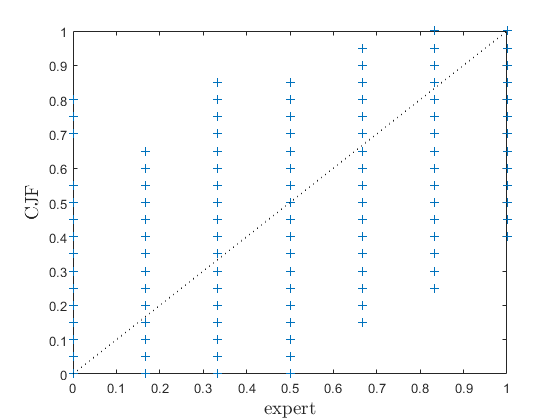


figure

%plot(objectTNG50.subfind(mask),objectCJF.subfind(indCJF(mask)),'.')
plot(score50,scoreCJF,'+')
hold on
plot([0 1],[0 1],':k')
xlabelmine('expert');
ylabelmine('CJF');

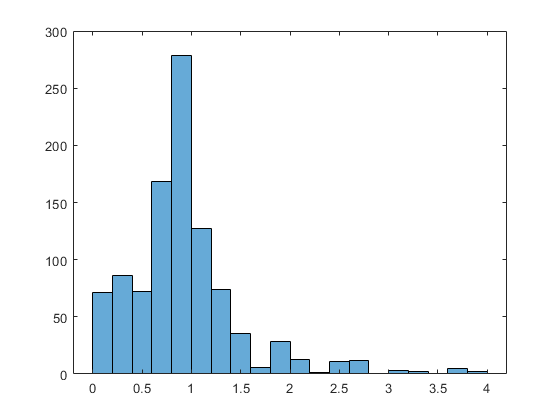



figure
histogram(scoreCJF./score50)

## plot JF heatmap

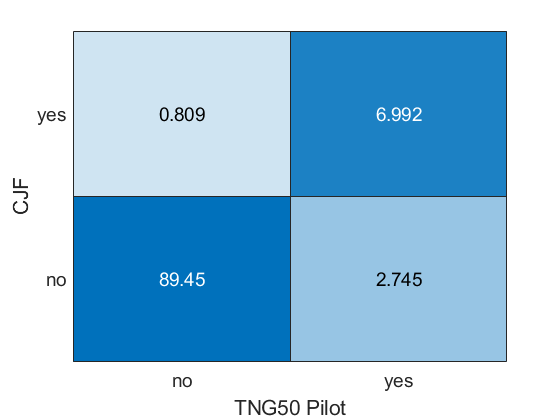

jfdata=[sum(jfCJF & ~jf50) , sum(jfCJF & jf50);...
    sum(~jfCJF & ~jf50) , sum(~jfCJF & jf50)]./3461*100;
ht=heatmap(["no " "yes "],["yes " "no "],jfdata);
ht.FontSize=14;
caxis([0 8])
colorbar('off')
ht.xlabel('TNG50 Pilot')
ht.ylabel('CJF')

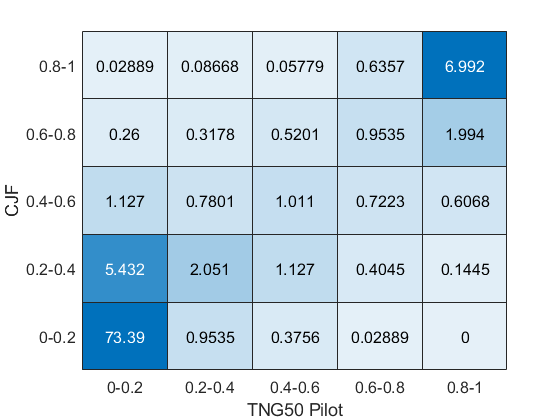



%d50=discretize(score50,0:0.2:1);
%dCJF=discretize(scoreCJF,0:0.2:1);
figure
edj=0:0.2:1;
edj(end)=1.1;
len=length(edj)-1;
cdata=zeros(len,len);
for i=1:len
    for j=1:len
        cdata(i,j)=sum((scoreCJF>=edj(i) & scoreCJF<edj(i+1)) & ...
            (score50>=edj(j) & score50<edj(j+1)) );
    end
end
 
 cdata=cdata./length(scoreCJF).*100;
 lab={'0-0.2' '0.2-0.4' '0.4-0.6' '0.6-0.8' '0.8-1'};
% imagesc(cdata)
% caxis([0 10])
% set(gca,'Ydir','normal','xtick',1:5,'xticklabel',lab,...
%     'ytick',1:5,'yticklabel',lab)
% colormap(cmap)

figure
ht=heatmap(lab,fliplr(lab),flipud(cdata));
caxis([0 7])
colorbar('off')
ht.xlabel('TNG50 Pilot')
ht.ylabel('CJF')
ht.FontSize=12;

fprintf('total agreement by bin (trace)= %s %% \n',num2str(trace(cdata)))

total agreement by bin (trace)= 84.3976 % 


fprintf("total agreement on what is or isn't JF (score>0.8)= %s %% \n",...
    num2str(sum(sum(sum(cdata(1:4,1:4)))+cdata(5,5))))

total agreement on what is or isn't JF (score>0.8)= 96.4461 % 
